clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
S =data_list_adamantane;

## import the data if already converted to ANA

for f = 1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata);
    data_converted(f) = macro.convert(data_corrected, mdata);
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv(f) = (S(f).photon);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.54513


Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.48224


Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.51938


## Plot AES

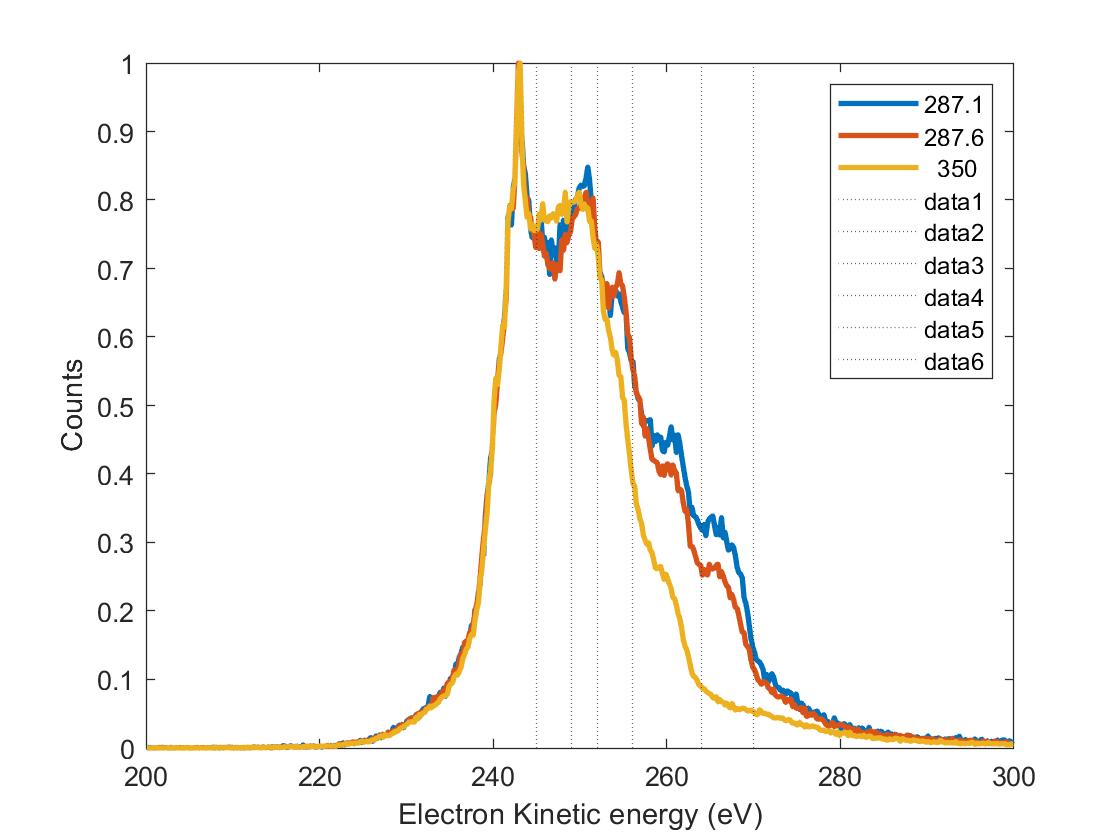

figure; hold on
for i=1:3
    [centres, electron_KE] = get_AES(data_converted(i), data_stats(i));
end
legend(num2str(hv')); box on
% xline([245 249 252 256 264 270] ,'LineStyle',':'); 
xline(245,'LineStyle',':'); xline(249,'LineStyle',':');
xline(252,'LineStyle',':'); xline(256,'LineStyle',':');
xline(264,'LineStyle',':'); xline(270,'LineStyle',':');

## Plot ES specific Ion TOF and m2q

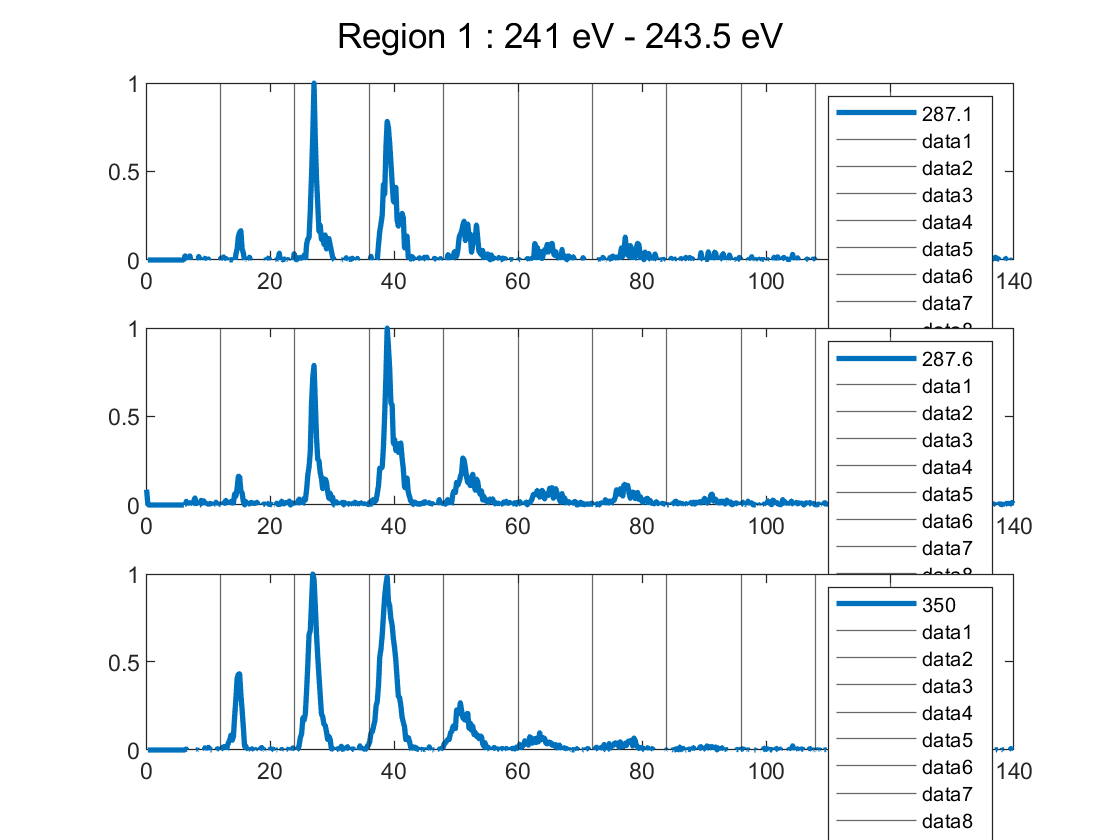

m2q_range =[0 ; 140];
figure; hold on
es_range = [241;243.5];
for i=1:3
    [TetEI_x_m2q,Xcenters,Ycenters] = get_pepico_m2q(data_converted(i), data_stats(i),m2q_range);
    idx = Xcenters>es_range(1) & Xcenters<es_range(2);
    m2q = sum(TetEI_x_m2q(idx,:));
    subplot(3,1,i)
    plot(Ycenters,m2q./max(m2q), 'DisplayName',num2str(hv(i)),'LineWidth',2)%
    legend
    ylim([0 1])
    for cc =1:10
        xline(12*cc);
    end
end
sgtitle(sprintf('Region 1 : %.0f eV - %.1f eV', es_range(1),es_range(2)))

## TOF and M2Q spectra All ions

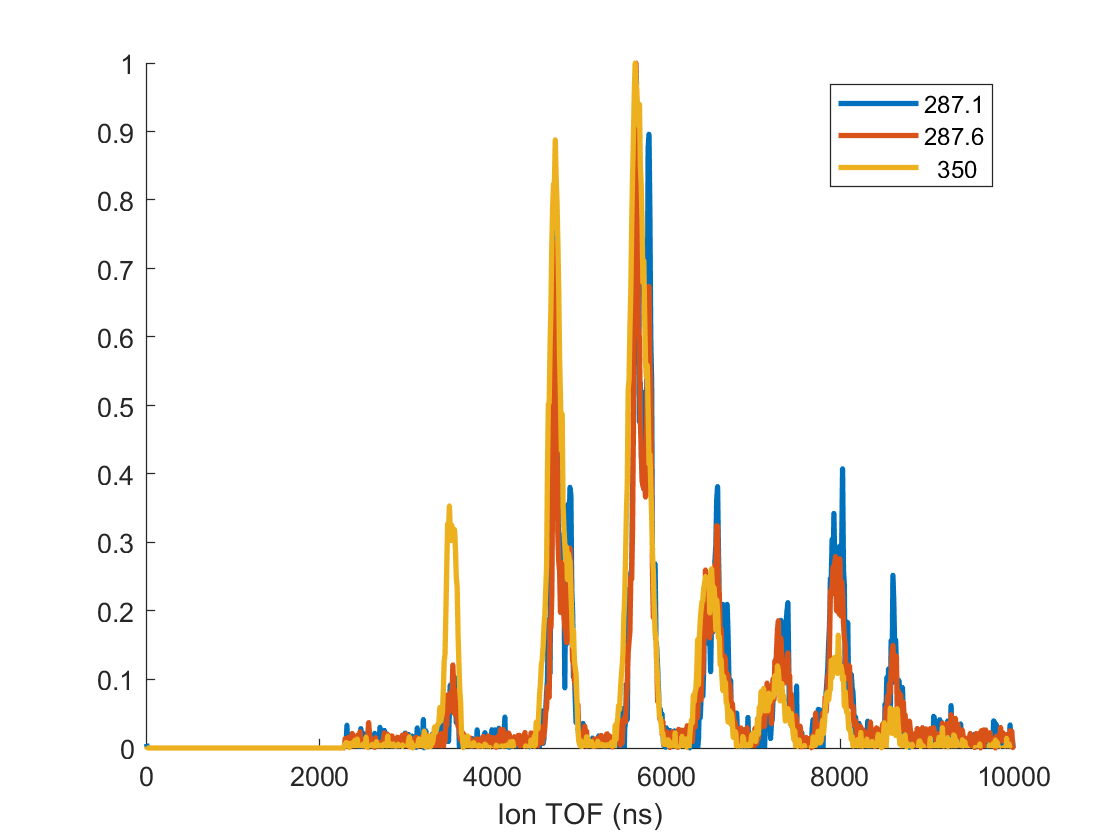

% [Tet_tof,Tet_tof_error] = plot_ion_tof(data_converted1, data_stats1);
figure; hold all
for i=1:3
    [Tet_tof,Tet_tof_error] = plot_mult_ion_tof(data_converted(i), data_stats(i), 2);
end
legend(num2str(hv'))
ylim([0 1])

% for kk =1:10
%     xline(12*(kk),'--');
% end


## ION Kinetic energy One ion events

% figure;
% m2q_range1 = get_m2q_range(data_converted(1), data_stats(1))
% m2q_range2 = get_m2q_range(data_converted(1), data_stats(1))
% m2q_range3 = get_m2q_range(data_converted(1), data_stats(1))

% figure; hold all
% for i=1:3
%     subplot(3,1,i)
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range1);
%     hold on
% %     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range2);
% %     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range3);
%     title(num2str(hv(i)))
%     legend
% end

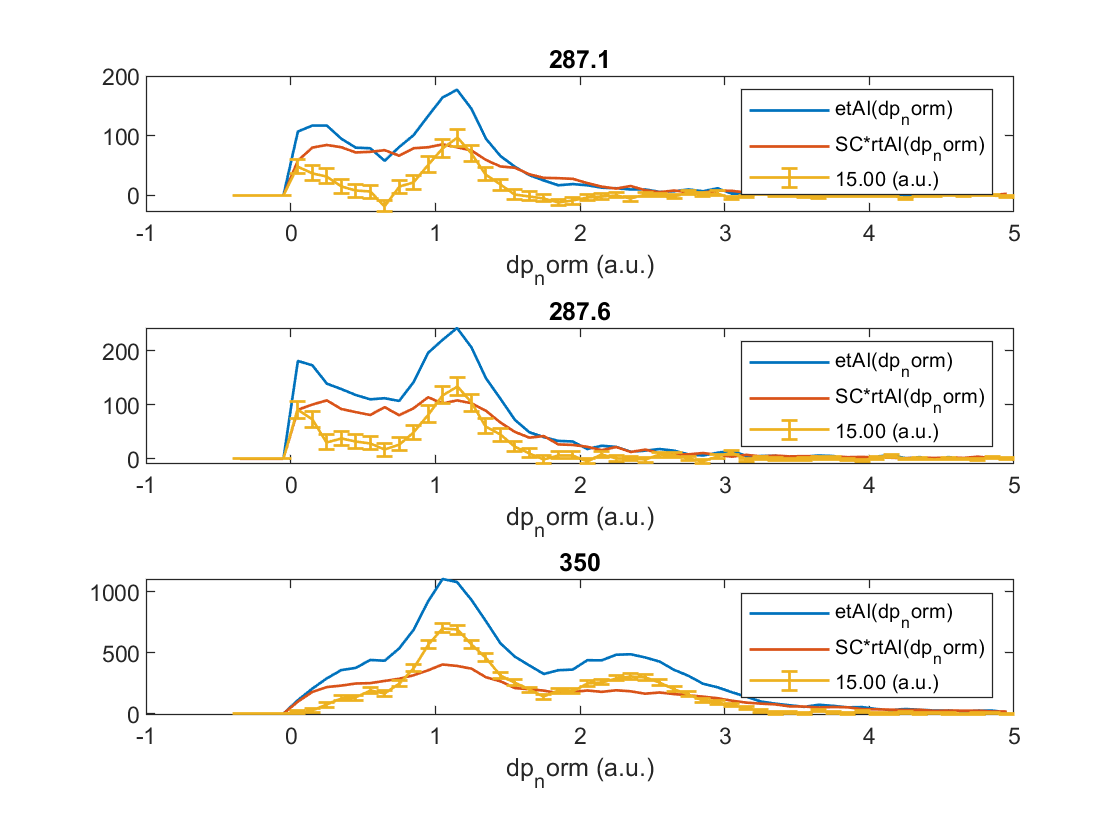

figure; hold all
for i=1:3
    subplot(3,1,i)
    [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',15);
    hold on
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range2);
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range3);
    title(num2str(hv(i)))
    legend
end


% ylim([0 1])

% figure
% [Tet_ke,Tet_ke_error] = plot_ion_ker(data_converted, data_stats,'m2q_label');

## Get ROI

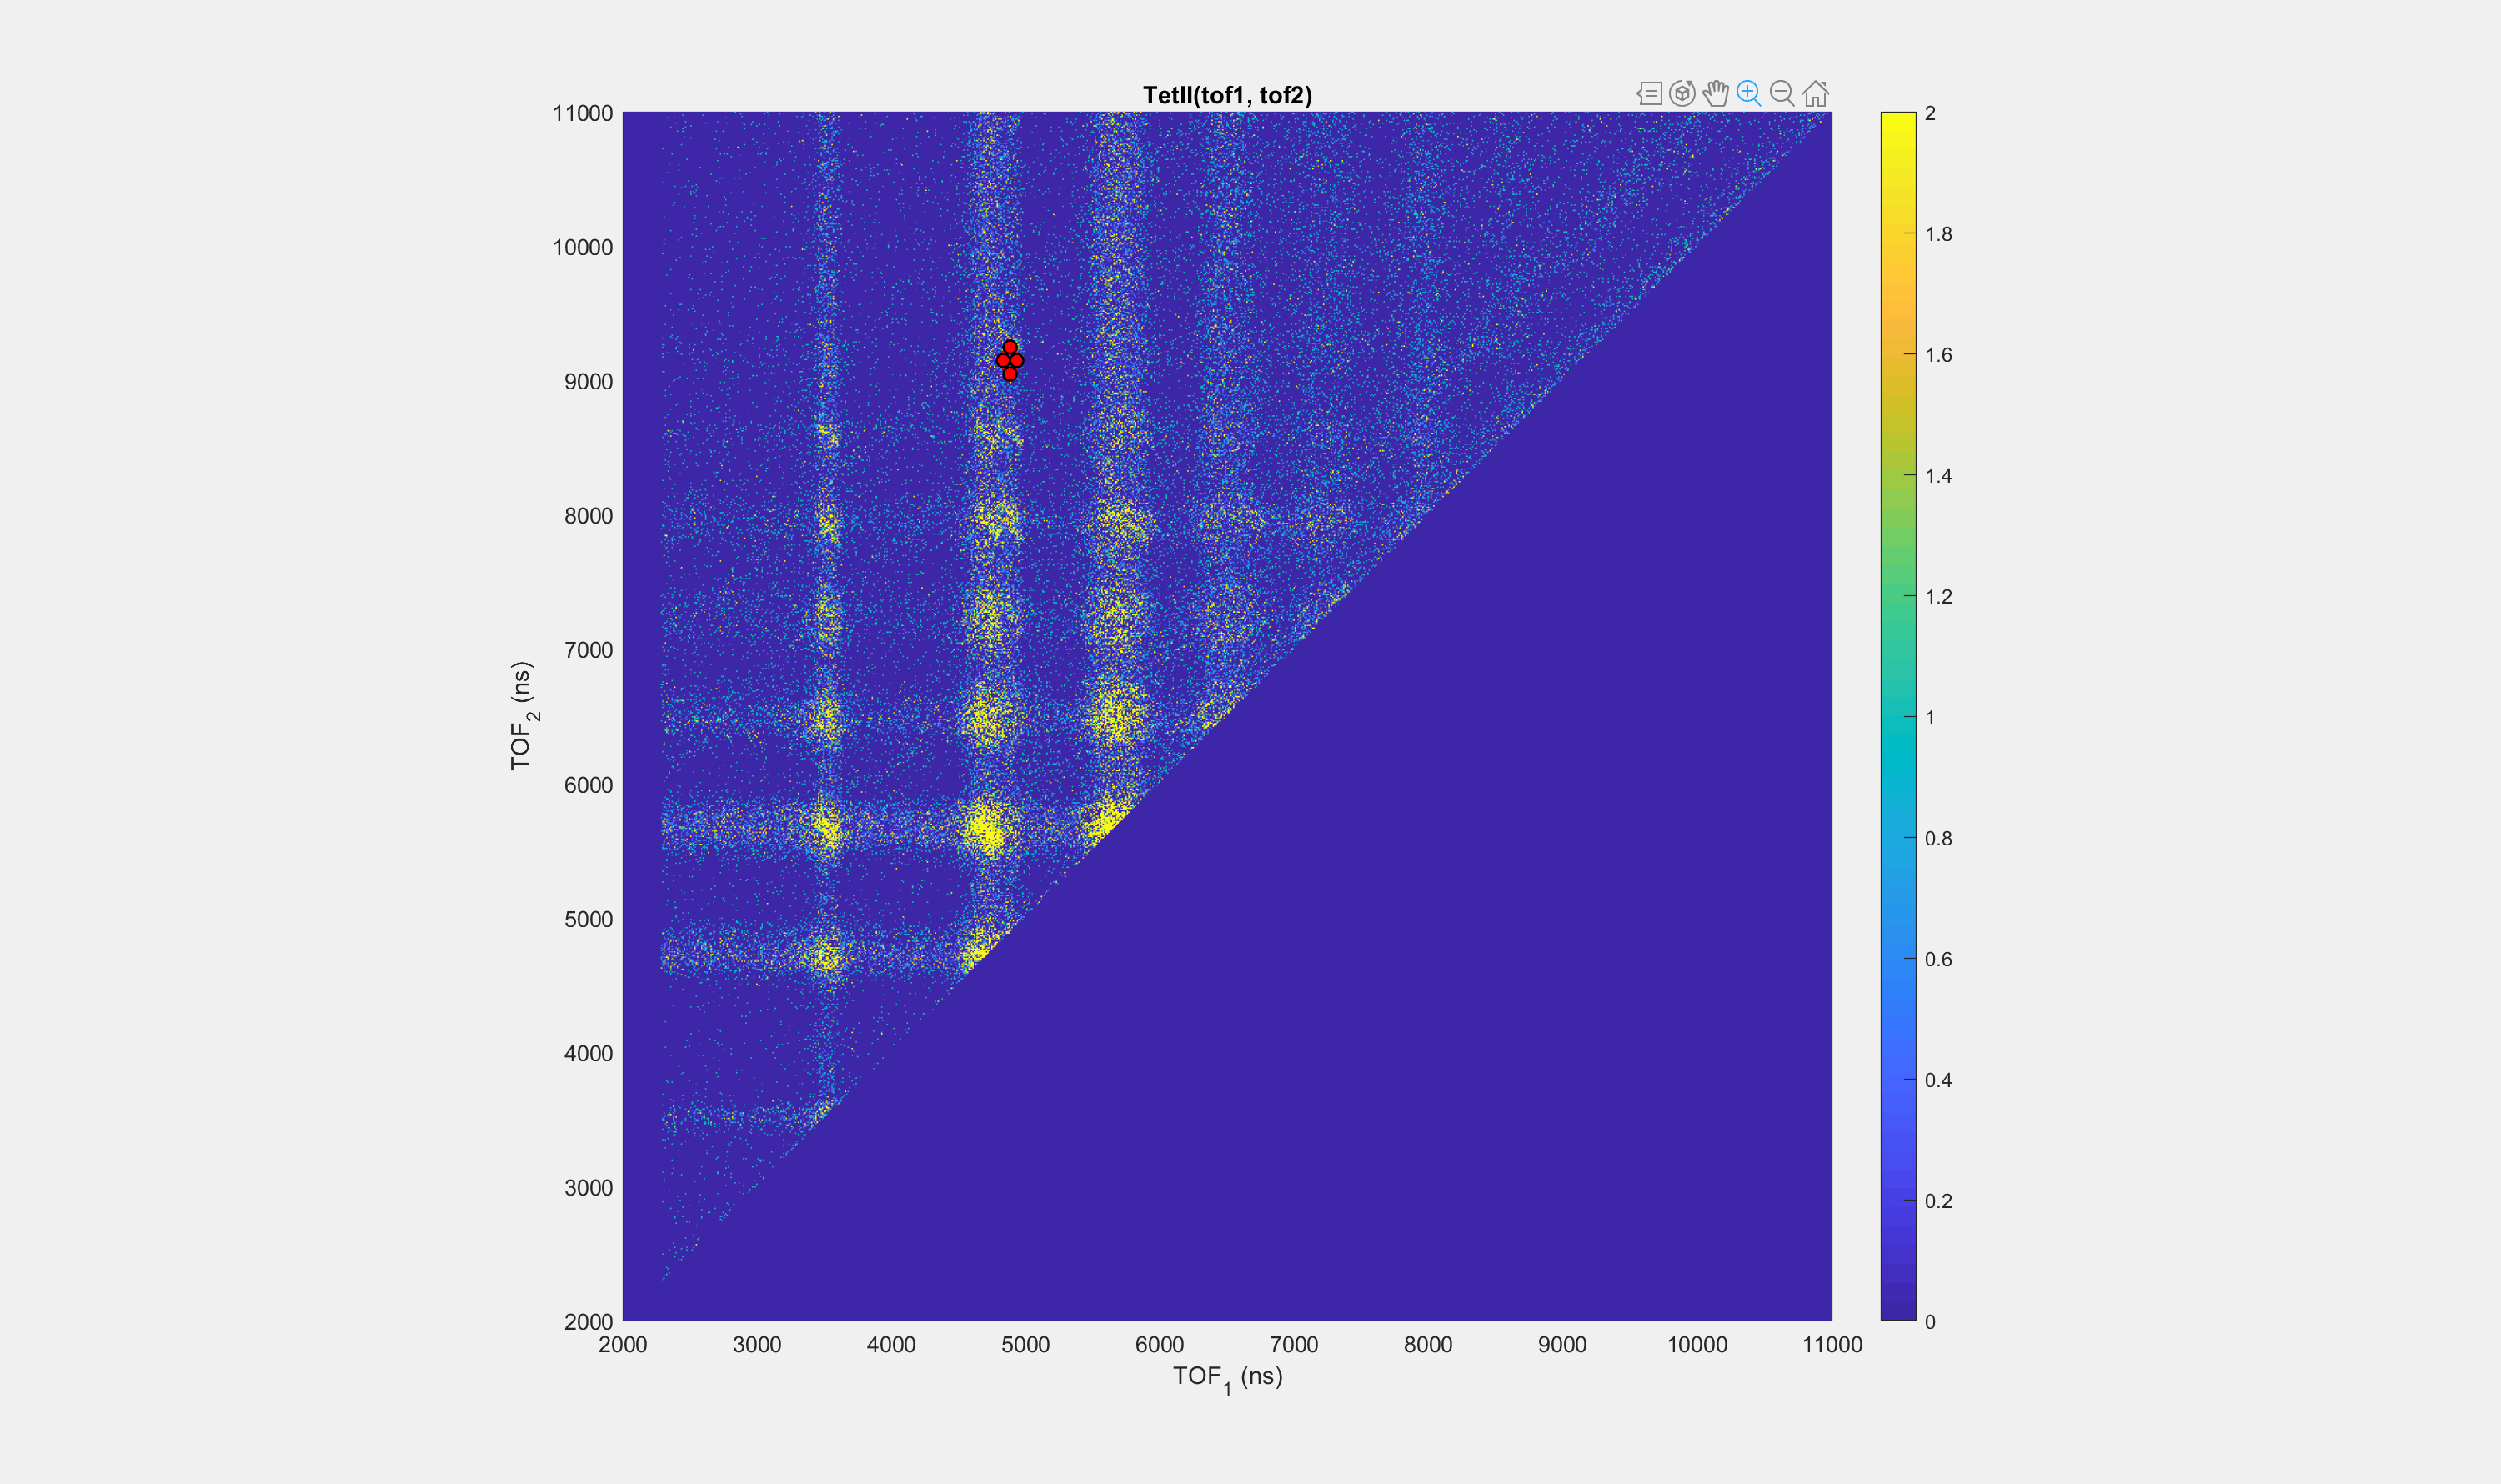

roi updated


m2q_1 = 12*2+1*5; m2q_2 = 12*8+1*7;
Center(1) = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
Center(2) = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);

[roi] = get_roi_pipico(data_converted(3), data_stats(3),Center);%%

## ION Kinetic energy Two ion events

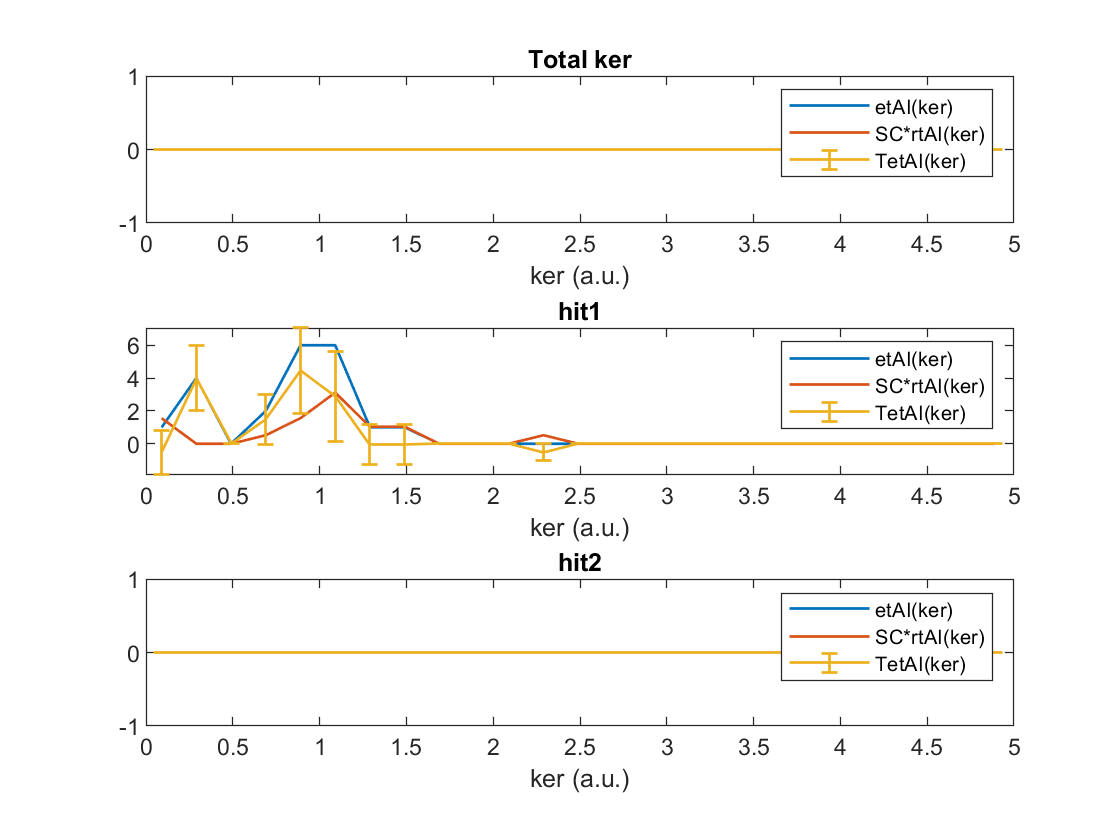

figure
plot_ion_ker_c2(data_converted(3), data_stats(3),roi)

% plot_ion_p_c2(data_converted(3), data_stats(3),mdata,m2q_1,m2q_2)
% plot_ion_psum_c2(data_converted(3), data_stats(3),mdata,m2q_1,m2q_2)

## PIPIC-O

figure; hold on
for i=1:3
    subplot(1,3,i)
    [Tet_tof2] = plot_pipico(data_converted(i), data_stats(i));
end

## PIPICO (ES FILTERED)

figure; hold on
es_range = [241;243.5];
for i=1:3
    subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2] = plot_pipico_es_filt(data_converted(i), data_stats_es_filt(i),es_range);
    title([num2str(hv(i)), ' eV'])
end
sgtitle(sprintf('Region 0 : %.0f eV - %.1f eV', es_range(1),es_range(2)))

## PEPICO

tof_range =[2000 ; 11000];
% tof_range =[4500 ; 5000];
figure; hold on
subplot(1,3,1)
 [TetEI_x_tof1,Xedges,Yedges] = plot_pepico(data_converted1, data_stats1,tof_range);
 subplot(1,3,2)
 [TetEI_x_tof2,Xedges,Yedges] = plot_pepico(data_converted2, data_stats2,tof_range);
 subplot(1,3,3)
 [TetEI_x_tof3,Xedges,Yedges] = plot_pepico(data_converted3, data_stats3,tof_range);

## Slices of PEPICO

% for jj=1:7;
C1=8; H1=9; H2=10; H3 =12;
m2q_1 = 12*C1+1*H1; m2q_2 = 12*C1+1*H2;  m2q_3 = 12*C1+1*H3; 
label1 =sprintf('C_%dH_{%d}^+', C1,H1);label2 =sprintf('C_%dH_{%d}^+', C1,H2); label3 =sprintf('C_%dH_{%d}^+', C1,H3);
tof1 = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof2 = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof3 = convert.m2q_2_TOF(m2q_3,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
% plot_pepico(data_converted1, data_stats1,[tof2-50;tof2+50 ]);

tof_centers = Yedges(1:end-1) + diff(Yedges) / 2; %tof values
energy_val = Xedges(1:end-1) + diff(Xedges) / 2;
id1 = tof_centers > tof1-50 & tof_centers < tof1+50;
id2 = tof_centers > tof2-50 & tof_centers < tof2+50;
id3 = tof_centers > tof3-50 & tof_centers < tof3+50;
 figure; 
 for i=1:3
    subplot(3,1,i); 
    y1 =sum(eval(sprintf('TetEI_x_tof%d(:,id1)', i)), 2);
    y2 =sum(eval(sprintf('TetEI_x_tof%d(:,id2)', i)), 2);
    y3 =sum(eval(sprintf('TetEI_x_tof%d(:,id3)', i)), 2);
    plot(energy_val,y1./max(y1),'DisplayName',label1,'LineWidth', 2); hold on
    plot(energy_val,y2./max(y2),'DisplayName',label2,'LineWidth', 2); hold on
    plot(energy_val,y3./max(y3),'DisplayName',label3,'LineWidth', 2);  
    ylim([0 1])
%      plot(energy_val,y1,'DisplayName',label1,'LineWidth', 2); hold on
%      plot(energy_val,y2,'DisplayName',label2,'LineWidth', 2); hold on
%     plot(energy_val,y3,'DisplayName',label3,'LineWidth', 2);  
    
    legend 
    title(hv{i})
    
 end
 
% end